# Review: Laplace transforms and LTI systems

Transfer functions are derived by computing the **Laplace transform** of **linear time-invariant** (**LTI**) dynamic systems. In this live script, the basics of Laplace transforms and LTI systems are reviewed.

## Laplace transform 

### Definition

The Laplace transform of a locally integrable function $f$ is 

    
$$F(s) = \mathcal{L}\{f(t)\} =\int_{0}^{\infty} f(t) e^{-st} \ dt$$


The corresponding inverse Laplace transform is denoted as

    
$$f(t) = \mathcal{L}^{-1} \{ F(s) \}$$


Inverse Laplace transforms (and forward Laplace transforms, for that matter) are usually found by appealing to a transform table. The formal definition of the inverse Laplace transform is rarely used and so is not discussed here.

**  Example. **

**(a) **Compute the Laplace transform of $f(t) = H(t-a)$ by hand, where $H$ is the Heaviside step function with $a > 0$.

**(b) **Compute the analytic Laplace transform of $f$ using the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html).

**Solution. **

**(a)**

    
$$\begin{array}{rl}
F(s) = \int_{0}^{\infty}  H(t-a) e^{-st} \ dt
 = \int_{a}^{\infty}  e^{-st} \ dt
= \left. -\frac{1}{s} e^{-st} \ \right\vert_a^\infty
= \frac{1}{s} e^{-as}
\end{array}$$


**(b) **The [`laplace`](https://www.mathworks.com/help/symbolic/laplace.html) function computes the analytic transform of a symbolic expression `f`. You can use the syntax:

1. Start by declaring symbolic variables. 

syms t s
syms a positive

2. Then, define the function `f`. You can find a list of mathematical functions present in the Symbolic Math Toolbox in [the documentation](https://www.mathworks.com/help/symbolic/mathematical-functions.html?s_tid=CRUX_lftnav).

f = heaviside(t-a)

$$f = \mathrm{heaviside}\left(t-a\right)$$

3. Finally, compute the Laplace transform with the input variable `t` and transform variable `s`.

Fs = laplace(f,t,s)

$$Fs = \frac{{\mathrm{e}}^{-a\,s}}{s}$$

**  Exercise. **

1. Compute the Laplace transform of some standard functions listed below on paper. Assume $a$ is real and $a>0$.


$$\textbf{a.}\ f(t) = 1 \qquad \textbf{b.} \ f(t) = e^{-at}  \qquad \textbf{c.} \ f(t) = t \qquad \textbf{d.}\ f(t) =  \delta(t-a)$$



$$\textbf{e.}\ f(t) = \cos(t) \qquad \textbf{f.}\ f(t) = t^2 e^{-at} \qquad \textbf{g.} \ f(t) =  e^{-at} \sin(t)$$


**Hints:** **a/b.** substitution, **c. **integration by parts, **d. **[`dirac`](https://www.mathworks.com/help/symbolic/sym.dirac.html) (for the symbolic computation), **e/g. **integrate by parts and rearrange terms, **f. **multiple integrations by parts, 

2. Verify your answers by computing the Laplace transforms in the space provided below using symbolic math.

% Symbolic variable declarations
syms t s
syms a positive

% Compute Laplace transforms here



### Visualize Laplace transforms

  **Try.** Use the controls below to visualize common Laplace transforms.

syms t real
syms a b positive

Set constants $m$, $a$, and $b$:

m = 1; % Positive integer
anum = 1; % Positive constant
bnum = 1; % Positive constant

Select a function $f$:

f = exp(-a*t)*cos(b*t); 

Define axis ranges:

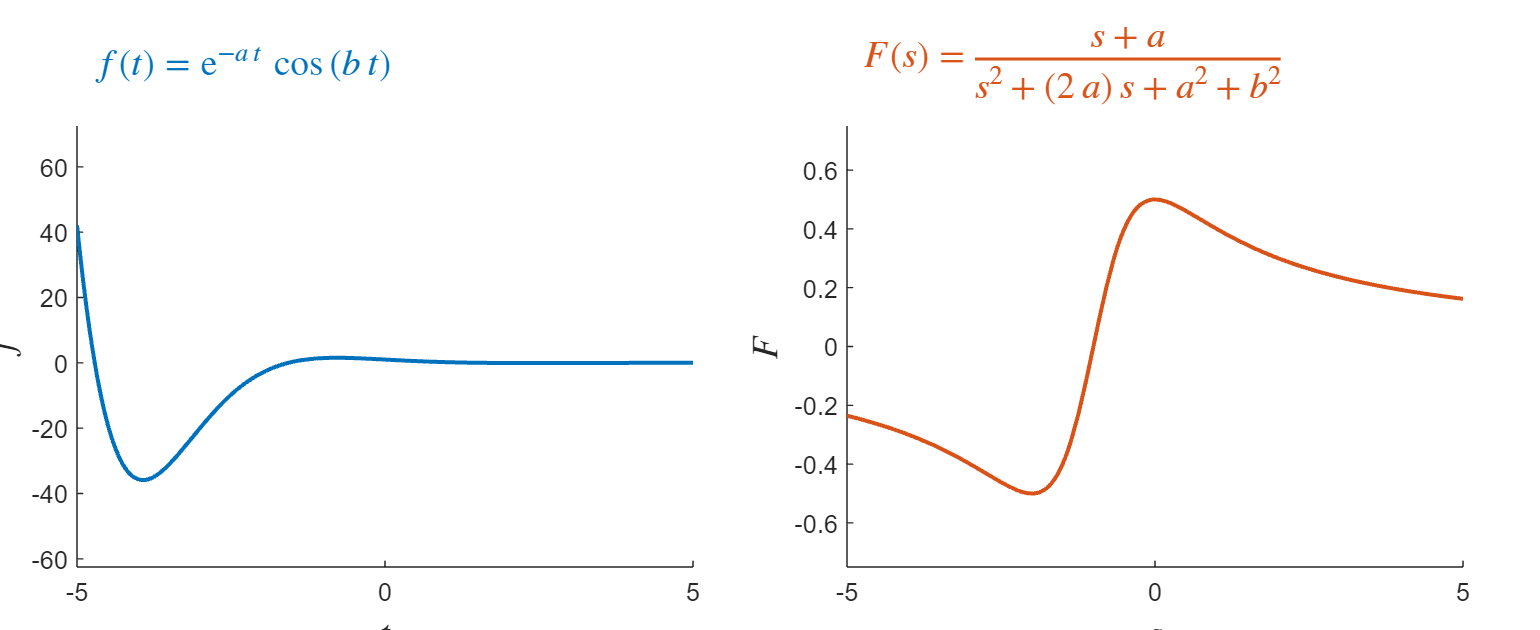

trange = [-5, 5];
srange = [-5, 5];

generateSinglePlot(f,anum,bnum,trange,srange); % This local function generates the plots

  **Reflect. **

- What class of functions is most commonly observed in the Laplace transform?

- How do the poles of the Laplace transform reflect the behavior of the time domain function $f(t)$?

Laplace transforms and their inverses are also commonly found using a table, like [this one](https://en.wikipedia.org/wiki/List_of_Laplace_transforms#Table).

### Laplace transform properties

Laplace transforms have several important properties that can be derived from the definition. A few essential properties are reviewed below.

    
$$\left.
\begin{array}{lll}
\textbf{Name} & \mathbf{f(t)} & \mathbf{F(s)}
\\
\text{Time derivative} \quad& \dot{f}(t) \quad & sF(s) - f(0)
\\
\text{Time integral} \quad& \int_0^t f(\tau) d\tau \quad & \frac{F(s)}{s}
\\
\text{Frequency shift} \quad& e^{at} f(t) \quad & F(s-a)
\\
\text{Time shift} \quad& f(t-a)H(t-a) \quad & e^{-as} F(s)
\\
\text{Time scaling} \quad& f(at) \quad & \frac{1}{a}F\left( \frac{s}{a}\right)
\\
\text{Time domain convolution} \quad &  (f*g)(t) & F(s) G(s)
\end{array}
\right.
$$


For example, the Laplace transform of a time derivative can be computed through integration by parts:

    
$$\begin{array}{rl}
\mathcal{L}\{f'(t)\} &= \int_{0}^{\infty}  \dot{f}(t) e^{-st} \ dt
\\
&= \left. f(t) e^{-st} \ \right\vert_0^\infty - \int_{0}^{\infty}  f(t) \left( -s  e^{-st}) \ dt
\\
&= - f(0) + sF(s)
\end{array}$$


  **Try.** The symbolic derivative of $f$ is defined below by declaring a [symbolic function](https://www.mathworks.com/help/symbolic/create-symbolic-functions.html) using the syntax 

The derivative is then computed using the [`diff`](https://www.mathworks.com/help/matlab/ref/diff.html) function. 

syms t f(t)
dfdt = diff(f)

$$dfdt(t) = \frac{\partial }{\partial t}f\left(t\right)$$

Use the [`laplace`](https://www.mathworks.com/help/symbolic/laplace.html) function to compute the Laplace transform of `dfdt` in the space below.

Fs = laplace(dfdt)

$$Fs = s\,\mathrm{laplace}\left(f\left(t\right),t,s\right)-f\left(0\right)$$

**  Exercise. **

**    a. **Find the formula for the Laplace transform of the second time derivative $\ddot{f}(t)$ by hand, using integration by parts twice.

**    b.** Verify your answer by computing the Laplace transform using symbolic math.

  **Pro-tip**: To compute the second derivative, use the [`diff`](https://www.mathworks.com/help/matlab/ref/diff.html) function with the syntax: `diff(f,n)`, where `n` is the order of the derivative.

syms t f(t) % Definitions of the symbolic variables
% Perform your symbolic computations here
d2fdt2 = diff(f,2)

$$d2fdt2(t) = \frac{\partial^{2}}{\partial t^{2}}f\left(t\right)$$

Fs = laplace(d2fdt2)

$$Fs = s^{2}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)-s\,f\left(0\right)-\left({\left(\frac{\partial }{\partial t}f\left(t\right)\right)|}_{t=0}\right)$$

### Visualize Laplace transform properties

  **Try. **Use the controls below to visualize the properties of Laplace transforms.

syms t real
syms a real

Set constants $m$ and $a$:

m = 1; % Positive integer
anum = 1; % Constant

Select a function $f$ and a property to create $g$.

f = sin(t);
g = diff(f);

Define axis ranges:

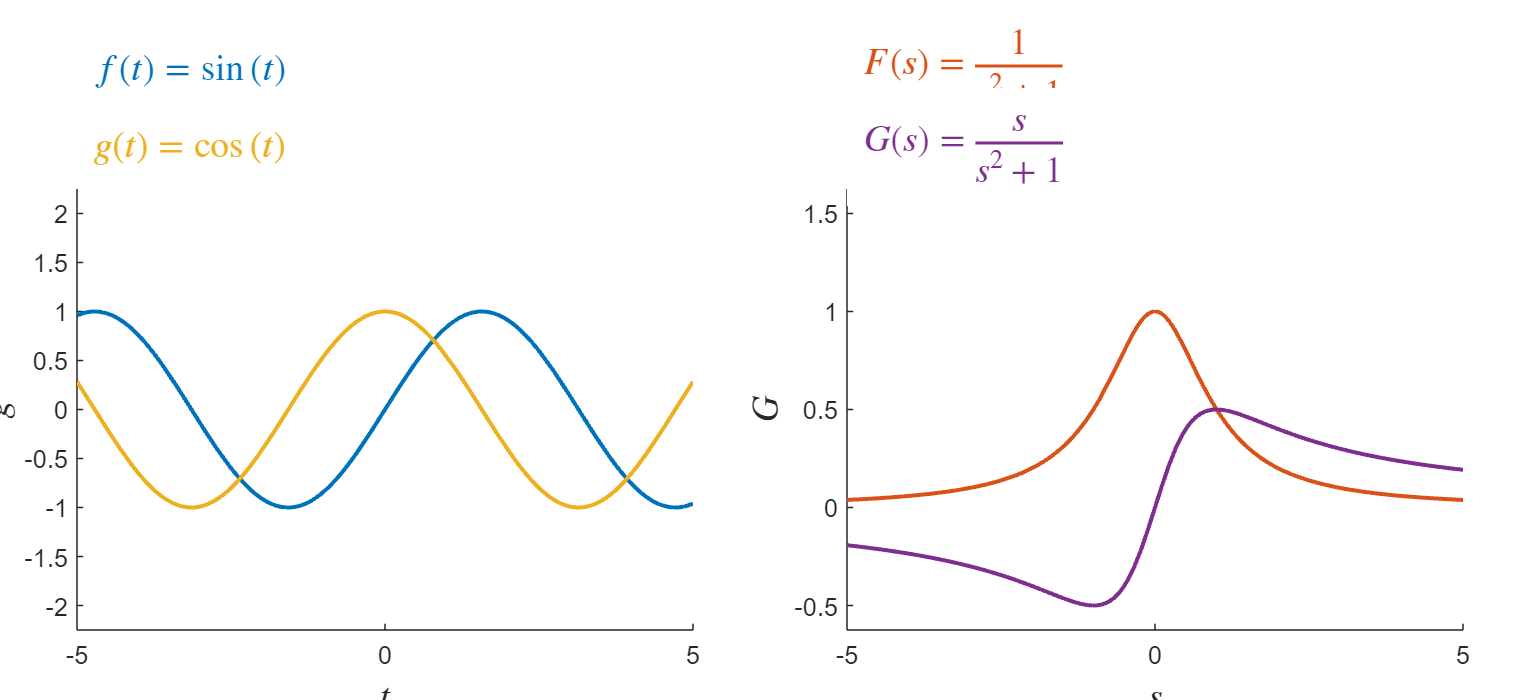

trange = [-5, 5];
srange = [-5, 5];

generateDoublePlot(f,g,anum,0,trange,srange) % This local function generates the plots

### Solving differential equations using the Laplace transform

You can solve initial value problems analytically using Laplace transforms. In general, this is accomplished by 

- taking the Laplace transform, 

- solving for the solution variable in the Laplace domain ($X(s)$), and

- taking the inverse Laplace transform by referring to a Laplace transform table.

**  Example. **Use the Laplace transform to solve for the dynamics of the mass-spring-damper with 

- constant forcing $F = 10$ N

- physical parameters: $m = 1$ kg, $c = 2$ N$\cdot$s/m, and $k = 10$ N/m

- zero initial conditions: $x(0) = 0$ and $x'(0)=0$

        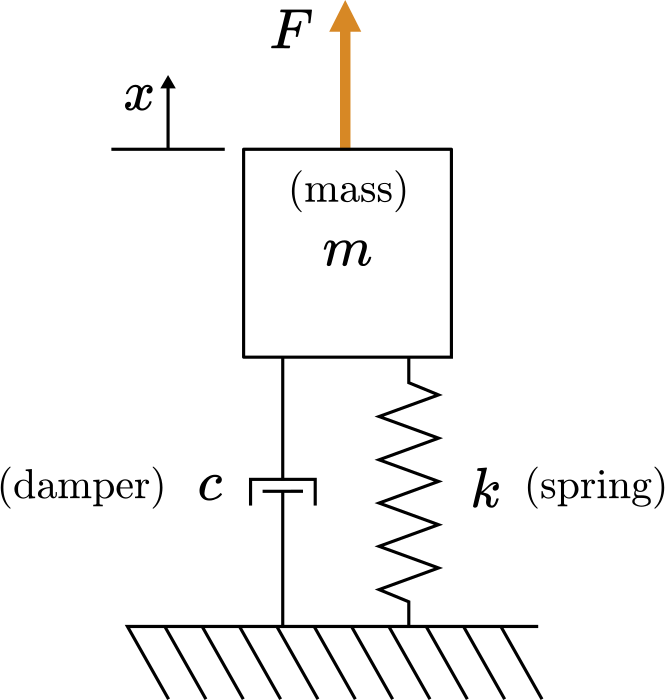

**Solution.**

**1. Derive the equations of motion.** You can draw a free body diagram and apply Newton's second law to derive the equations of motion.

        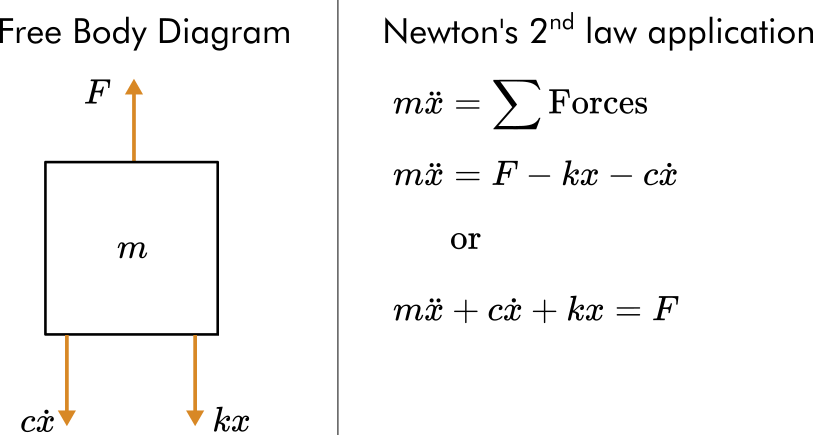

**2. Compute the Laplace transform of the dynamic system ODE and solve for **$X.$ Note: $\mathcal{L}\{x(t)\} = X(s)$.

    
$$\mathcal{L} \left\{ m \ddot{x} + c\dot{x} + kx = F \right\} \rightarrow$$

$$m[s^2 X - sx(0) - x'(0)] + c [s X - x(0)] + kX = \frac{F}{s}$$


Applying the zero initial conditions and the values of the physical parameters implies

    
$$s^2 X + 2 s X  + 10X = \frac{10}{s}$$


Solving for $X$ yields

    
$$X = \frac{10}{s^3 + 2  s^2   + 10s }$$


**3. Use partial fraction decomposition to separate the expression for **$X$** into terms where the inverse Laplace transform is known**

Try performing the partial fraction decomposition on paper and comparing your result to the symbolic solution found below.

% Define X(s)
syms s 
X = 10/(s^3 + 2*s^2 + 10*s)

$$X = \frac{10}{s^{3}+2\,s^{2}+10\,s}$$

% Compute the partial fraction decomposition
Xdecomp = partfrac(X,s)

$$Xdecomp = \frac{1}{s}-\frac{s+2}{s^{2}+2\,s+10}$$

**4. Take the inverse Laplace transform**

You can take the inverse Laplace transform by rewriting $X$ as a sum of terms in forms found on a [transform table](https://en.wikipedia.org/wiki/List_of_Laplace_transforms#Table).


$$X(s) = \frac{1}{s}-\frac{s+2}{s^2 +2 \ s+10} =  \frac{1}{s}-\frac{s+2}{(s + 1)^2 + 9}  =  \frac{1}{s}-\frac{s+1}{(s + 1)^2 + 3^2}  -\frac{1}{3}\frac{3}{(s + 1)^2 + 3^2}$$


The solution is then constructed by taking the inverse transform:


$$\begin{array}{rl}
x(t) &= \mathcal{L}^{-1} \left\{ \frac{1}{s}-\frac{s+1}{(s + 1)^2 + 3^2}  -\frac{1}{3}\frac{3}{(s + 1)^2 + 3^2} \right\}
\\
  &= H(t) - H(t) e^{-t} \cos( 3 t) - \frac{1}{3} H(t) e^{-t} \sin(3t)
\\
  &= H(t)( 1  - e^{-t} \cos( 3 t) - \frac{1}{3} e^{-t} \sin(3t))
\end{array}$$


Alternatively, you can use the symbolic function [`ilaplace`](https://www.mathworks.com/help/symbolic/sym.ilaplace.html) to find the inverse Laplace transform of $X(s)$.

syms x
x = ilaplace(X) % The inverse Laplace transform of X(s)

$$x = 1-{\mathrm{e}}^{-t}\,\left(\cos\left(3\,t\right)+\frac{\sin\left(3\,t\right)}{3}\right)$$

**5. Plot the solution**

Click the checkbox to plot the solution.

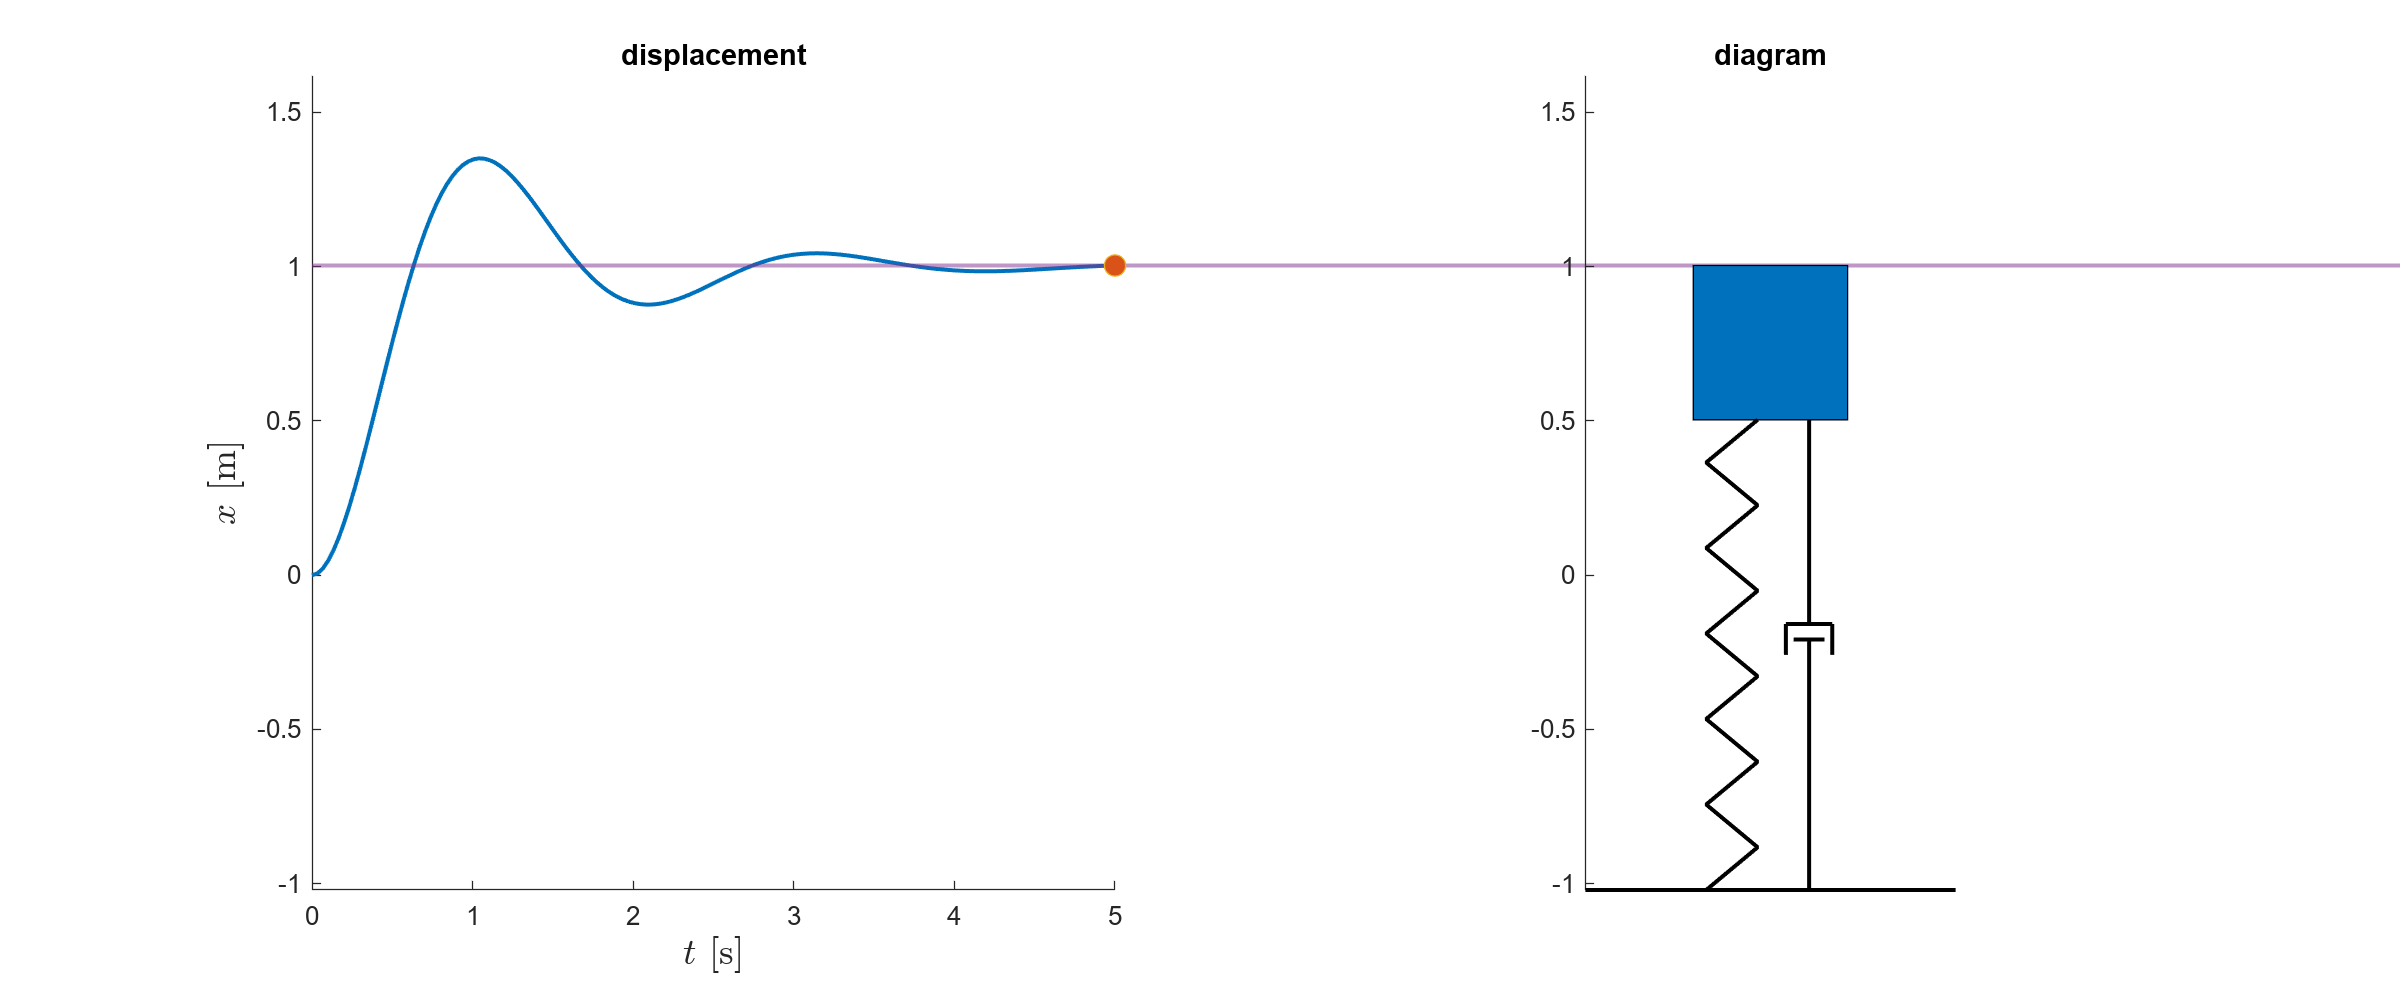

plotSoln = true;

% Create solution array
t = linspace(0,5,150);
x = 1-exp(-t).*(cos(3*t) + 1/3*sin(3*t));
% This generates a plot (do not edit)
if(plotSoln)
    animateSingleMSD(t,x,0.5)
end

**  Exercise. **In this exercise, you will solve for the dynamics of the simple pendulum using the Laplace transform.

              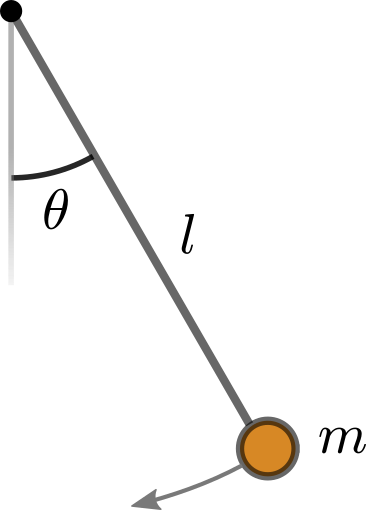

**(a) **Draw a free-body diagram for the simple pendulum shown above and derive the equation of motion for a pendulum with length $l = 0.5$ m and a gravitational constant of 9.8 m/s. Linearize the equation near $\theta = 0$ and show that it is equivalent to

    
$$\ddot \theta + 19.6 \theta = 0$$
  

**(b) **Use the Laplace transform to solve the linearized equations of motion:

    
$$\ddot \theta + 19.6 \theta = 0$$
  

   with initial conditions $\theta(0) = \pi / 6, \ \dot \theta (0) = 0$.

Write your solution in the variable `theta` in terms of the symbolic variable `t`. Then click the checkbox to plot your solution.

syms t
% Replace NaN with your symbolic solution and run the section
theta = NaN; 

plotSoln = false; 
% This generates a plot (do not edit)
if(plotSoln)
    plotPendulum(theta)
end

## Linear time-invariant systems

Linear time-invariant (LTI) systems are characterized by the two properties stated in the name: linearity and time-invariance. 

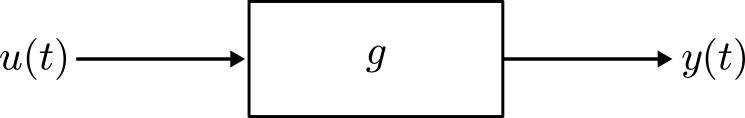

*Consider an operator *$g$* that maps an input *$u(t)$* to an output *$y(t)$*. *

**1. Linearity**

The operator $g$ is linear if it has two properties:

- Superposition: $g[u_1(t) + u_2(t)] = y_1(t) + y_2(t)$

- Homogeneity: $g[au(t)] = ay(t)$

Often these two properties are written together as

    
$$g[a u_1(t) + bu_2(t)] = ay_1(t) + by_2(t)$$


**2. Time invariance**

The operator $g$ is time-invariant if a time-shifted input produces an output with the same time shift:

- 
$$g[u(t - \tau)]= y(t - \tau)$$


**  Exercise. **In this exercise, you will identify if several unknown operators are linear and time-invariant by examining their outputs.

**a.** Identify if the operators $g$, $h$, $i$, and $j$ are **time-invariant** by examining the graphs of their inputs and outputs.

- Use the dropdown to change the operator.

- Adjust `tau` to change the time-shift of the input.

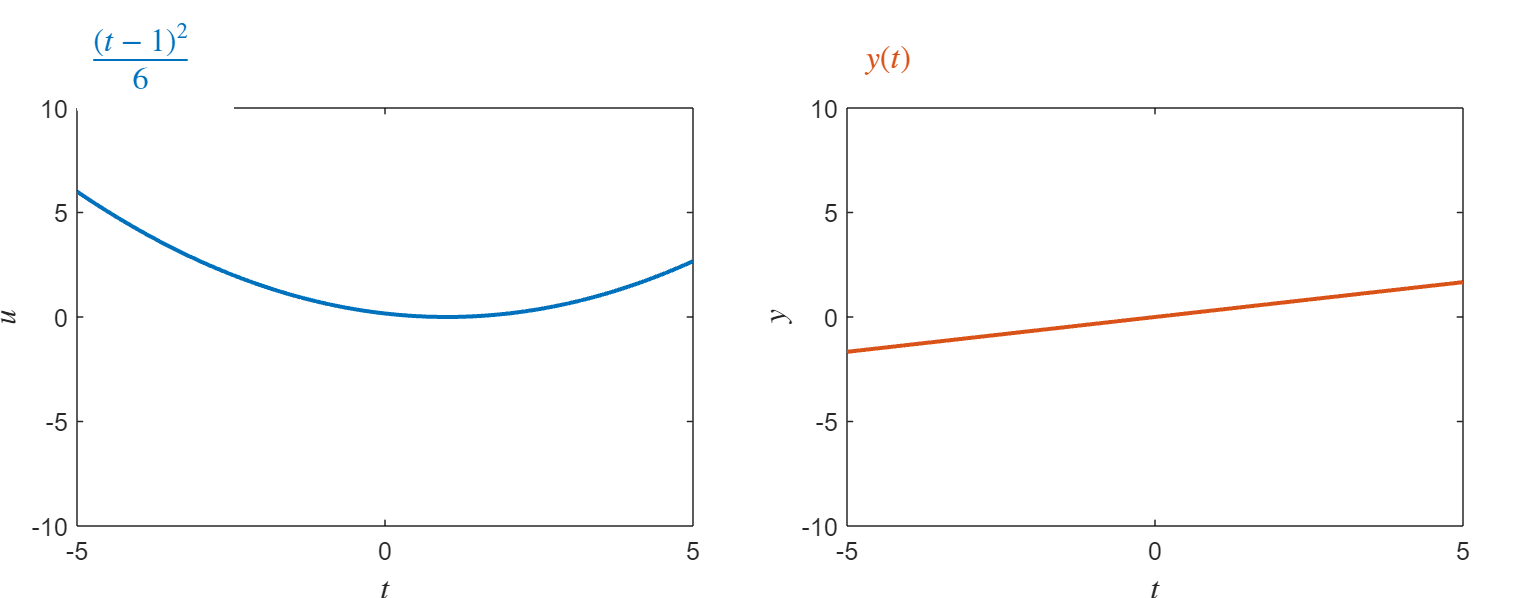

syms t
operator = "g"; % Select an operator
u = t^2/6; % Input function
tau = 1; 

plotInputsOutputs(u,tau,1,operator) 

**b.** Identify if the operators $g$, $h$, $i$, and $j$ satisfy the **homogeneity **condition ($g[au(t)] = ay(t)$) by examining the graphs of the inputs and outputs.

- Use the dropdown to change the operator.

- Adjust `a` to change the scaling of the input.

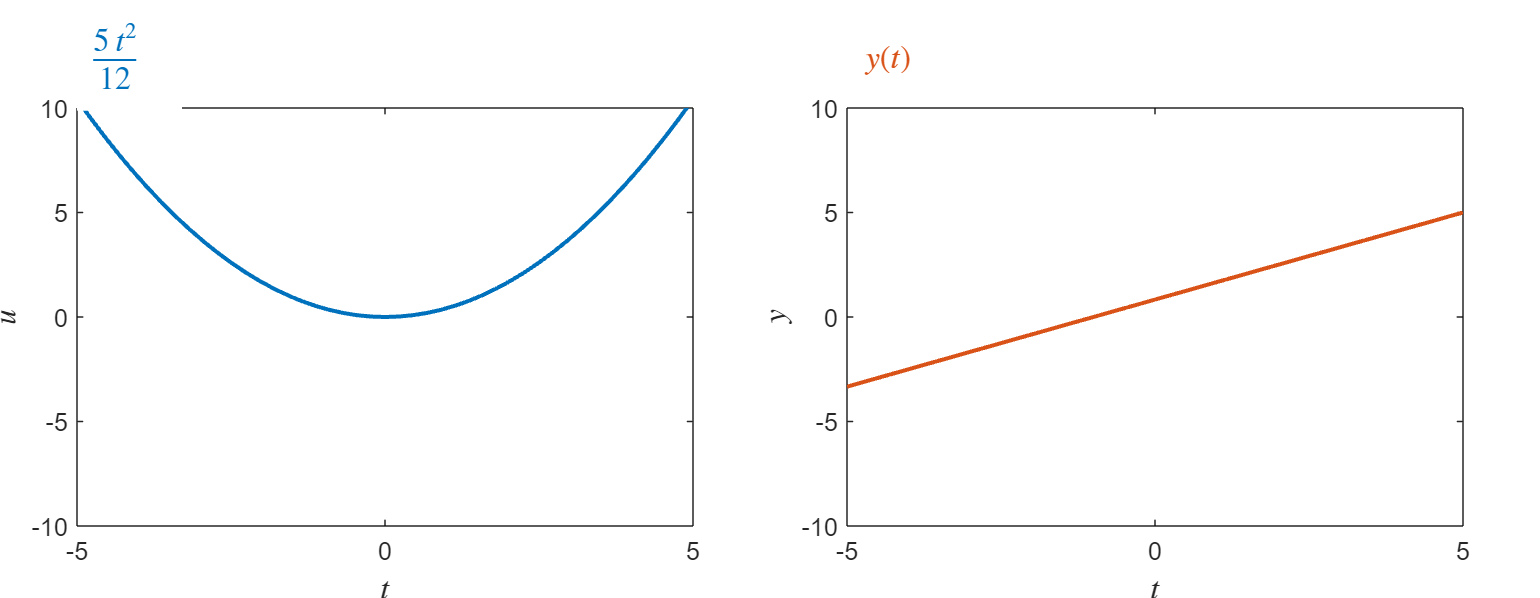

operator = "g";
syms t
u = t^2/6; % Input function
a = 2.5; 

plotInputsOutputs(u,0,a,operator) 

**c.** Identify if the operators $g$, $h$, $i$, and $j$ satisfy **superposition**: $g[u_1(t) + u_2(t)] = y_1(t) + y_2(t)$ by examining the graphs of the inputs and outputs.

- Use the dropdown to change the operator.

- Try different functions for $u_1$ and $u_2$.

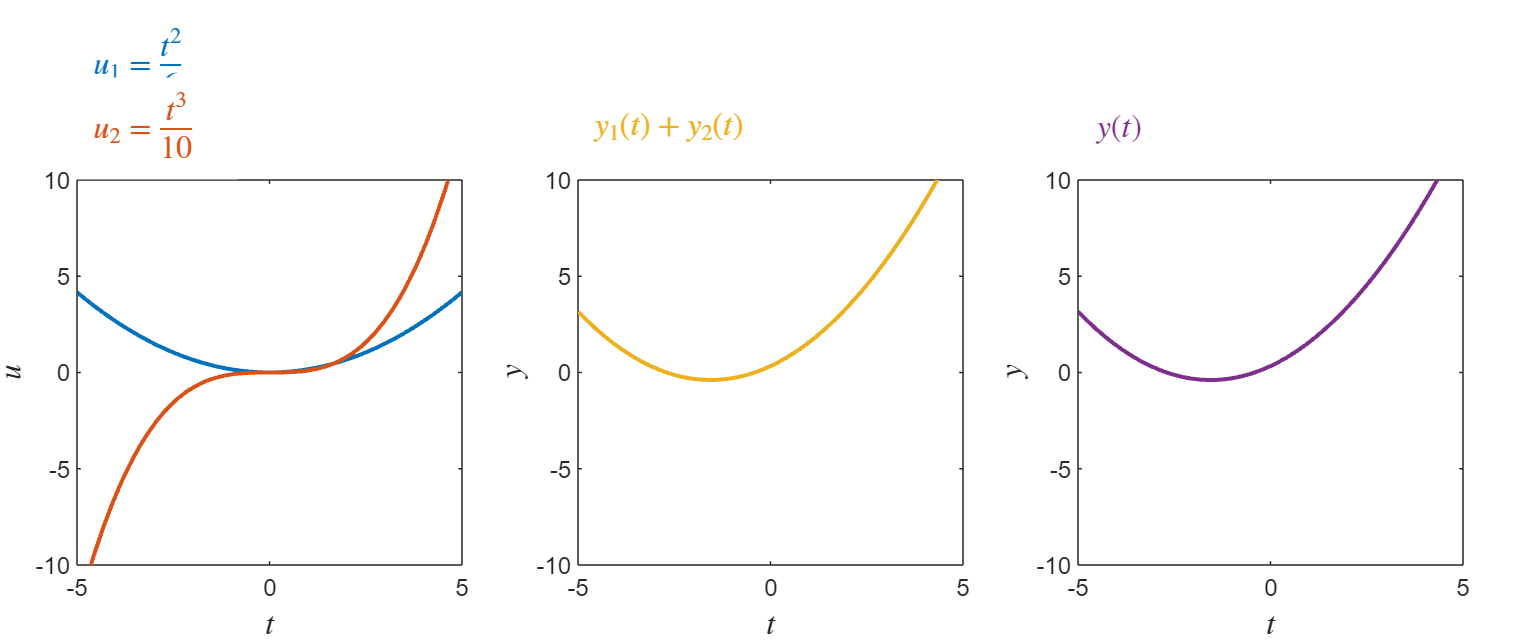

operator = "g";
syms t
u1 = t^2/6; % Input function 1
u2 = t^3/10; % Input function 2

plotAddition(u1,u2,operator)

  **Reflect. **The simple operators used to generate the graphs above are listed below. Which operators are linear? Which are time-invariant? Do your answers match what you observed in the graphs above?

- $g$: $y(t) = g[u(t)]$ with $g= \frac{d}{dt}  + \frac{d^2}{dt^2}$

- $h$: $y(t) = 4 \sin^2[u(t)]$

- 
$$i: \ y(t) = \int_{t - 1}^{t + 1} 3u(\tau) d\tau$$


- $j$: $y(t) = t \frac{d}{dt} u(t)$

**Helper functions**

**Plots**

function generateSinglePlot(f,anum,bnum,trange,srange)
% This function plots a single transform pair
    colors = lines(2);
    figure("position",[0 0 1100 450])
    plotLaplace(f,anum,bnum,trange,srange,colors(1,:),colors(2,:),0.05,0.55,0.85,0.7) 
end

function generateDoublePlot(f,g,anum,bnum,trange,srange)
% This function plots two transform pairs together
    colors = lines(4);
    figure("position",[0 0 1100 500])
    plotLaplace(f,anum,bnum,trange,srange,colors(1,:),colors(2,:),0.05,0.55,0.85,0.63) % This local function generates the plots
    plotLaplace(g,anum,bnum,trange,srange,colors(3,:),colors(4,:),0.05,0.55,0.74,0.63) % This local function generates the plots
end
 
function plotLaplace(func,anum,bnum,trange,srange,c1,c2,p1,p2,py,vpos)
% This function plots a transform pair
    fs = 14; % fontsize
    funcName = inputname(1);
    
    % Compute the Laplace transform and generate functions
    syms s
    syms t real
    syms a b positive
    Fs = laplace(sym(func),t,s);
    Fs = collect(Fs);
    
    % Generate functions for plotting
    ffunc = matlabFunction(sym(func),"vars",[t a b]);
    Fsfunc = matlabFunction(Fs,"vars",[s a b]);
    fplotfunc = @(t)ffunc(t,anum,bnum);
    Fplotfunc = @(s)Fsfunc(s,anum,bnum);

    % Plot f(t) and label it with a latex function
    subplot("position",[0.05 0.1 0.4 vpos])
    hold on
    if(func == dirac(t-a))
        hold on
        plot([1,1]*anum,[0,1],"color",c1,"linewidth",1.5)
        plot(anum,1,"^","color",c1,"linewidth",1.5,"MarkerFaceColor",c1)
        plot(trange,0*trange,"linewidth",1.5,"color",c1)
        hold off
    elseif(func == 1)
        plot(trange,0*trange,"linewidth",1.5,"color",c1)
    else
        fplot(fplotfunc,trange,"linewidth",1.5,"color",c1)
    end
    hold off
    xlabel("$t$","Interpreter","latex","fontsize",fs)
    frange = get(gca,'ylim');
    frange = [frange(1) - diff(frange)/4, frange(2) + diff(frange)/4 ];
    axis([trange frange])
    ylabel("$"+funcName+"$","Interpreter","latex","fontsize",fs)
    textVal = "$$"+funcName+"(t) = "+latex(sym(func))+"$$";
    annotation("textbox","String",textVal,"Interpreter","latex","Color",c1,"VerticalAlignment","middle",...
        "fontsize",fs,"Position",[p1 py 0.1 0.1],"FitBoxToText","on","EdgeColor","none","BackgroundColor","white")
    
    % Plot F(s) and label it with a latex function
    subplot("position",[0.55 0.1 0.4 vpos])
    hold on
    if( Fs == 1 )
        plot(srange,0*srange,"linewidth",1.5,"color",c2)
    else
        fplot(Fplotfunc,srange,"linewidth",1.5,"color",c2)
    end
    hold off
    xlabel("$s$","Interpreter","latex","fontsize",fs)
    ylabel("$"+upper(funcName)+"$","Interpreter","latex","fontsize",fs)
    Frange = get(gca,'ylim');
    Frange = [Frange(1) - diff(Frange)/4, Frange(2) + diff(Frange)/4];
    axis([srange Frange])
    textVal = "$$"+upper(funcName)+"(s) = "+latex(sym(Fs))+"$$";
    annotation("textbox","String",textVal,"Interpreter","latex","Color",c2,"VerticalAlignment","middle",...
        "fontsize",fs,"Position",[p2 py 0.1 0.1],"FitBoxToText","on","EdgeColor","none","BackgroundColor","white")

end

function plotInputsOutputs(u,tau,a,operator)
% Plots operator input/output and annotates the plots with latex
    figure("position",[0 0 900 350])
    tlims = [-5 5];
    ylims = [-10 10];
    colors = lines(2);
    c1 = colors(1,:);
    c2 = colors(2,:);
    p1 = 0.05;
    p2 = 0.55;
    py = 0.85;
    vpos = 0.70;

    fs = 12; % fontsize
    
    % Apply operator and generate functions
    syms t
    u = a*subs(u,t,t-tau);
    uFunc = matlabFunction(u,"var",t);
    y = applyOperator(u,operator);
    yFunc = matlabFunction(y,"var",t);

    % Plot u(t) and label it with a latex function
    subplot("position",[0.05 0.12 0.4 vpos])
    fplot(uFunc,tlims,"linewidth",1.5,"color",c1)
    xlabel("$t$","Interpreter","latex","fontsize",fs)
    axis([tlims ylims])
    ylabel("$u$","Interpreter","latex","fontsize",fs)
    textVal = "$$"+latex(sym(u))+"$$";
    annotation("textbox","String",textVal,"Interpreter","latex","Color",c1,"VerticalAlignment","middle",...
        "fontsize",fs,"Position",[p1 py 0.1 0.1],"FitBoxToText","on","EdgeColor","none","BackgroundColor","white")
    
    % Plot y(t) and label it with a latex function
    subplot("position",[0.55 0.12 0.4 vpos])
    fplot(yFunc,tlims,"linewidth",1.5,"color",c2)
    xlabel("$t$","Interpreter","latex","fontsize",fs)
    ylabel("$y$","Interpreter","latex","fontsize",fs)
    axis([tlims ylims])
    textVal = "$$y(t)$$";
    annotation("textbox","String",textVal,"Interpreter","latex","Color",c2,"VerticalAlignment","middle",...
        "fontsize",fs,"Position",[p2 py 0.1 0.1],"FitBoxToText","on","EdgeColor","none","BackgroundColor","white")
end

function plotAddition(u1,u2,operator)

    figure("position",[0 0 1200 500])
    tlims = [-5 5];
    ylims = [-10 10];
    colors = lines(5);
    c1 = colors(1,:);
    c2 = colors(2,:);
    c3 = colors(3,:);
    c4 = colors(4,:);
    px1 = 0.05;
    px2 = 0.375;
    px3 = 0.7;
    py1 = 0.85;
    py2 = 0.75;
    vpos = 0.60;

    fs = 12; % fontsize
    
    % Apply operator and generate functions
    syms t
    u = u1 + u2;
    uFunc = matlabFunction(u,"var",t);
    u1Func = matlabFunction(u1,"var",t);
    u2Func = matlabFunction(u2,"var",t);
    
    y = applyOperator(u,operator);
    y1 = applyOperator(u1,operator);
    y2 = applyOperator(u2,operator);
    yFunc = matlabFunction(y,"var",t);
    y12Func = matlabFunction(y1+y2,"var",t);

    % Plot u(t) and label it with a latex function
    subplot("position",[px1 0.12 0.25 vpos])
    fplot(u1Func,tlims,"linewidth",1.5,"color",c1)
    hold on
    fplot(u2Func,tlims,"linewidth",1.5,"color",c2)
    hold off
    xlabel("$t$","Interpreter","latex","fontsize",fs)
    axis([tlims ylims])
    ylabel("$u$","Interpreter","latex","fontsize",fs)
    textVal = "$$u_1 = "+latex(sym(u1))+"$$";
    annotation("textbox","String",textVal,"Interpreter","latex","Color",c1,"VerticalAlignment","middle",...
        "fontsize",fs,"Position",[px1 py1 0.1 0.1],"FitBoxToText","on","EdgeColor","none","BackgroundColor","white")
    textVal = "$$u_2 = "+latex(sym(u2))+"$$";
    annotation("textbox","String",textVal,"Interpreter","latex","Color",c2,"VerticalAlignment","middle",...
        "fontsize",fs,"Position",[px1 py2 0.1 0.1],"FitBoxToText","on","EdgeColor","none","BackgroundColor","white")
    
    % Plot y(t) and label it with a latex function
    subplot("position",[px2 0.12 0.25 vpos])
    fplot(y12Func,tlims,"linewidth",1.5,"color",c3)
    xlabel("$t$","Interpreter","latex","fontsize",fs)
    ylabel("$y$","Interpreter","latex","fontsize",fs)
    axis([tlims ylims])
    textVal = "$$y_1(t) + y_2(t)$$";
    annotation("textbox","String",textVal,"Interpreter","latex","Color",c3,"VerticalAlignment","middle",...
        "fontsize",fs,"Position",[px2 py2 0.1 0.1],"FitBoxToText","on","EdgeColor","none","BackgroundColor","white")

    % Plot F(s) and label it with a latex function
    subplot("position",[px3 0.12 0.25 vpos])
    fplot(yFunc,tlims,"linewidth",1.5,"color",c4)
    xlabel("$t$","Interpreter","latex","fontsize",fs)
    ylabel("$y$","Interpreter","latex","fontsize",fs)
    axis([tlims ylims])
    textVal = "$$y(t)$$";
    annotation("textbox","String",textVal,"Interpreter","latex","Color",c4,"VerticalAlignment","middle",...
        "fontsize",fs,"Position",[px3 py2 0.1 0.1],"FitBoxToText","on","EdgeColor","none","BackgroundColor","white")

end

function y = applyOperator(u,operator)
    syms t
    if(operator == "g")
        y = diff(u,1) + diff(u,2);
    elseif(operator == "h")
        y = 4*sin(u).^2;
    elseif(operator == "i")
        y = int(3*u,t,t-1,t+1);
    else
        y = t*diff(u,1);
    end
end
 
function plotPendulum(thetaSym)
    try
        % This generates a plot (do not edit)
        t = linspace(0,5,150);
        thetaFunc = matlabFunction(thetaSym);
        thetaArray = thetaFunc(t);
        generatePendulumPlot(t,thetaArray,0.5)
    catch ME
        warning("Plotting failed with error: " + ME.message)
    end
end

function generatePendulumPlot(t,theta,l)
% Generates an animation of a single pendulum
% t: time array
% theta: angle array
% l: length of pendulum
    
    colors = lines(6);
    ms = 8;
    fs = 14;
    
    f = figure("position",[0,0,1200,700]);
    % Generate solution variables
    tlim = [min(t),max(t)];
    y = -l*cos(theta);
    x = l*sin(theta);
    
    % Setup the figure
    buff = 1.2;
    ymax = max([l/2,max(y)*buff]);
    axisLim0 = [tlim(1),tlim(2),min(theta)*buff,max(theta)*buff];
    axisLim1 = [tlim(1),tlim(2),-l*buff,ymax];
    axisLim2 = [-l*buff,l*buff,-l*buff,ymax];
    
    k = 1;
    % Create plot
    sp0 = subplot(2,2,1);
    xlabel("$t$","Interpreter","latex","fontsize",fs)
    ylabel("$\theta$","Interpreter","latex","fontsize",fs)
    hold on
    plot(t,theta,"color",colors(1,:),"linewidth",1.5);
    b = plot(t(k),theta(k),"o","markerfacecolor",colors(2,:),"markersize",ms);
    hold off
    axis(axisLim0)
    title("Angular displacement")
    box off
    
    sp1 = subplot(2,2,3);
    set(gca, "Clipping","off","Color","none"); 
    hold on
    plot(t,y,"k-","color",colors(1,:),"linewidth",1.5)
    e = plot([0, tlim(2)+(tlim(2)-tlim(1))*4], [y(k),y(k)],"-","color",[colors(4,:),0.5],"linewidth",1.5);
    f = plot([t(k), t(k)], [-l*buff,ymax+(ymax+l*buff)*4],"-","color",[colors(4,:),0.5],"linewidth",1.5);
    g = plot(t(k),y(k),"o","markerfacecolor",colors(2,:),"markersize",ms);
    hold off
    axis(axisLim1)
    box off
    xlabel("$t$ [s]","Interpreter","latex","FontSize",fs)
    ylabel("$y$ [m]","Interpreter","latex","FontSize",fs)
    title("Vertical position")
    
    sp2 = subplot(2,2,4);
    set(gca, "Clipping","off","Color","none");
    hold on
    d = plot([0,x(k)],[0,y(k)],"color",colors(1,:),"linewidth",1.5);
    c = plot(x(k),y(k),"o","markerfacecolor",colors(2,:),"markersize",ms*1.5);
    hold off
    axis equal
    axis(axisLim2)
    box off
    xlabel("$x$ [m]","Interpreter","latex","FontSize",fs)
    ylabel("$y$ [m]","Interpreter","latex","FontSize",fs)
    title("Position")
    
    % Create animation
    for k = 1:length(t)
        b.XData = t(k);
        b.YData = theta(k);
        c.XData = x(k);
        c.YData = y(k);
        d.XData = [0,x(k)];
        d.YData = [0,y(k)];
        e.YData = [y(k),y(k)];
        f.XData = [t(k),t(k)];
        g.XData = t(k);
        g.YData = y(k);
        pause(0)
    end
    drawnow
    close all
end


function animateSingleMSD(t,x,w)
% Generates an animation of a single mass/spring/damper
% t: time array
% x: displacement array
% w: width of the mass

    colors = lines(6); 
    fs = 14;
    
    % Create plot
    k = 1;
    f = figure("position",[0 0 1200 500]);
    
    % Setup the figure
    buffer = 1.2;
    xrange = max(x) - min(x);
    xmax = min(x) + xrange*buffer ;
    xmin = max(x) - xrange*buffer - w*1.5;
    tlim = [t(1) t(end)];
    axisLim1 = [tlim(1),tlim(2),xmin,xmax];
    axisLim2 = [-w*buffer,w*buffer,xmin,xmax];
    xground = xmin;
        
    sp1 = subplot(1,2,1);
    set(gca, "Clipping","off","Color","none"); 
    hold on
    plot(t,x,"k-","color",colors(1,:),"linewidth",1.5);
    a = plot([0, tlim(2)+(tlim(2)-tlim(1))*4], [x(k),x(k)],"-","color",[colors(4,:),0.5],"linewidth",1.5);
    b = plot(t(k),x(k),"o","markerfacecolor",colors(2,:),"MarkerSize",8);
    hold off
    axis(axisLim1)
    box off
    xlabel("$t$ [s]","Interpreter","latex","FontSize",fs)
    ylabel("$x$ [m]","Interpreter","latex","FontSize",fs)
    title("displacement")
        
    sp2 = subplot(1,2,2);
    set(gca, "Clipping","off","Color","none");
    hold on
    plot([-w*buffer w*buffer],[xground xground],'k-',"linewidth",1.5);
    
    % Plot mass
    x1 = x(k) - w/2;
    c = rectangle("Position",[-w/2 x1-w w w],"FaceColor",colors(1,:));
    
    % Plot spring
    xextension = x(k)-w;       
    xs = linspace(xground,xextension,12);
    ys = w/6*(-1).^(1:numel(xs)) - w/4;
    d = plot(ys,xs,"k","linewidth",1.5);
    % Plot damper
    ydamp = w/4;

    xdamp1 = xground + (xextension-xground)/2 + w*0.1;
    xdamp2 = xground + (xextension-xground)/2;
    xdamp3 = xground + (xextension-xground)/2 + w*0.2;
    e = plot([ydamp,ydamp,NaN,ydamp-w/10,ydamp+w/10],[xground,xdamp1,NaN,xdamp1,xdamp1],"k","linewidth",1.5);
    f = plot([ydamp-w*0.15,ydamp-w*0.15,NaN,ydamp+w*0.15,ydamp+w*0.15,NaN,ydamp-w*0.15,ydamp+w*0.15,NaN,ydamp,ydamp],...
        [xdamp2,xdamp3,NaN,xdamp2,xdamp3,NaN,xdamp3,xdamp3,NaN,xdamp3,xextension],"k","linewidth",1.5);
    
    hold off
    axis equal
    axis(axisLim2)
    ax = gca;
    ax.XAxis.Visible = 'off'; 
    title("diagram")

    % Create animation
    for k = 1:length(t)
        % displacement
        a.YData = [x(k),x(k)];
        b.XData = t(k);
        b.YData = x(k);
        % mass
        c.Position = [-w/2,x(k)-w,w,w];
        xextension = x(k)-w;       
        % spring
        d.YData = linspace(xground,xextension,12);
        % damper
        xdamp1 = xground + (xextension-xground)/2 + w*0.1;
        xdamp2 = xground + (xextension-xground)/2;
        xdamp3 = xground + (xextension-xground)/2 + w*0.2;
        e.YData = [xground xdamp1 NaN xdamp1 xdamp1];
        f.YData = [xdamp2 xdamp3 NaN xdamp2 xdamp3 NaN xdamp3 xdamp3 NaN xdamp3 xextension]; 
        pause(0)
    end
    drawnow
    close all
        
end


% Suppress unused suggestions
%#ok<*NASGU> 